%  Разбор данных

RollVel
YawVel
YawAcc
XYZ.Y


% запись путей
addpath(genpath('E:\ExchangeRateStability\MotorcycleBooks\Models'))

% Прописываем пути к данным
PathsDan=struct('Work', 'E:\ExchangeRateStability\Log', 'Home', 'E:\MotoDan\mU');
PathsDan.Work

ans = 'E:\ExchangeRateStability\Log'


danfiles=cell(1);
danfiles{1}="T1_2021-10-06";          % 1
danfiles{2}="T1_2021-10-06_1";        % 2
danfiles{3}="T1_2021-10-06_2";        % 3
danfiles{4}="T3_2021-10-08_10-33";    % 4
danfiles{5}="T4_2021-10-08_10-36";    % 5
danfiles{6}="T5_2021-10-08_10-44";    % 6  трамплин
danfiles{7}="T6_2021-10-08_11-28";     % 7  


%load('-mat', 'E:\MotoDan\mU\T1_2021-10-06')

%T1Load = LoadDan(PathsDan.Work, danfiles(2));
%T2Load = LoadDan(PathsDan.Work, danfiles(3));
%T = LoadDan(PathsDan.Work, danfiles{7});

% Тест данных
verMatlab = 2017;
basaTitle = "T4 povorot long ";
SetParamFFT = struct('step', 1, 'nfft', 128, 'limit', 64);  
SetParamInfo = struct('Title', basaTitle, 'Ver', verMatlab);  
SetPathX = struct('Dir', PathsDan.Work, 'Files', danfiles{5})

testDan1 = AnalysisDan1(SetPathX, SetParamInfo);
testDan1.vBelt(["vBelt.R"]);

SetPathX = struct with fields:
      Dir: 'E:\ExchangeRateStability\Log'
    Files: "T4_2021-10-08_10-36"


pathfile = "E:\ExchangeRateStability\Log\T4_2021-10-08_10-36.mat"

vBelt.R


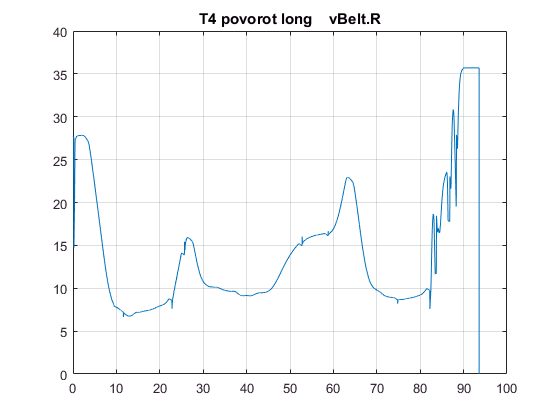

testDan1.Proskal();
testDan1.Engine();

vBelt.R
Engine.Rotv


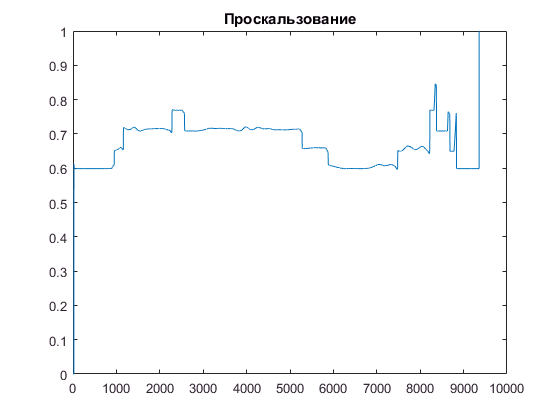

%testDan1.PlotXnames(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"]);

Engine.Trq
Engine.Rotv


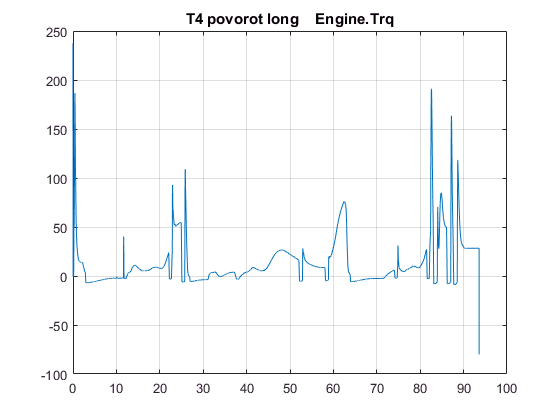

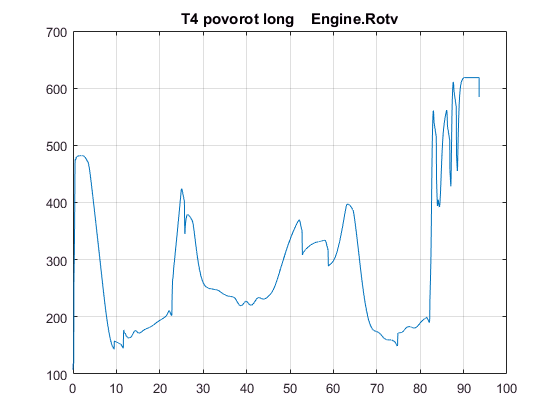

%zout=testDan1.Spectrum(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);

%testDan1.PlotXnames(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
%zout=testDan1.Spectrum(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);

%testDan1.PlotXYZg(["PitchVel", "RollVel", "YawVel", "YawAcc"])
%testDan.PlotXYZ()
% testDan1.vBelt();
% proskal = testDan1.Proskal();
%testDan1.PlotXnames(["PitchVel","YawVel", "YawAcc", "Engine.Trq", "Engine.Rotv", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
% zout=testDan1.Spectrum(["YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);
% testDan1.PlotXnames(["Frc.X", "Frc.Z", "muRoad.R"]);
% testDan1.mU();     

Speed
Engine.Rotv


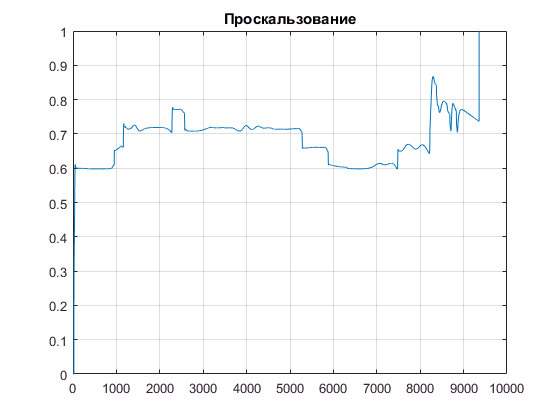

testDan1.Proskal();

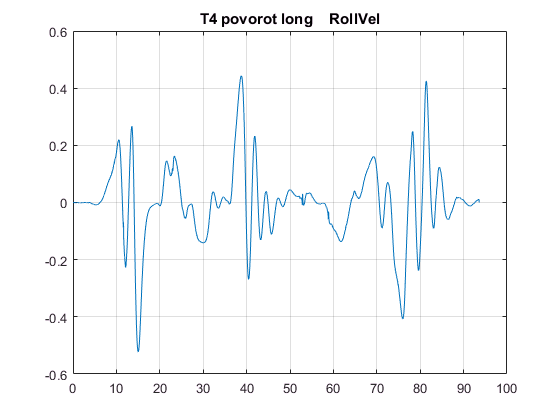

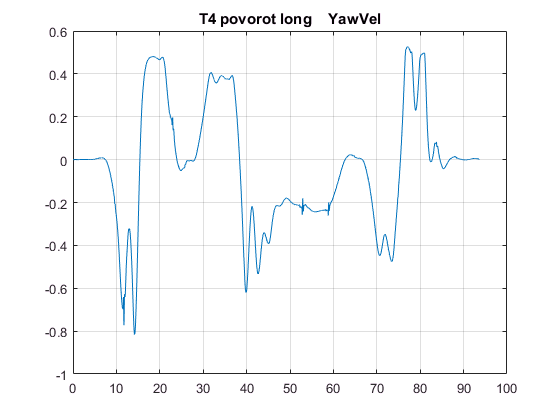

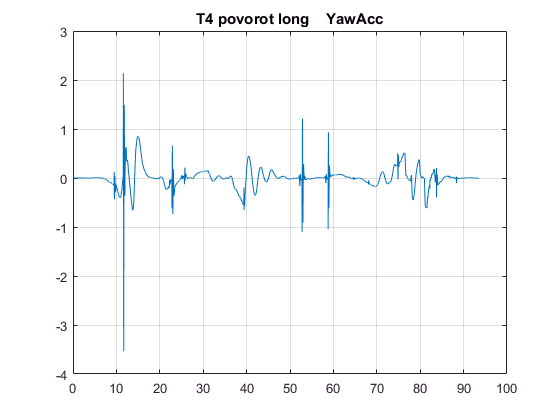

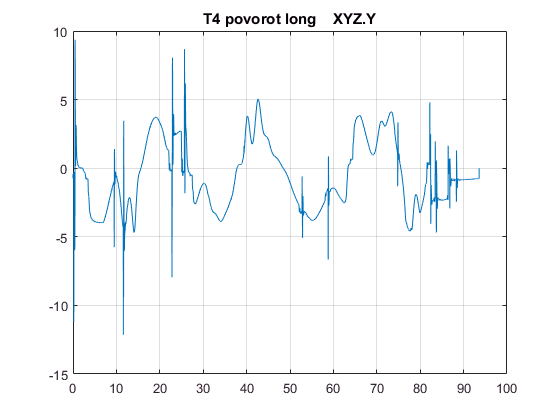

testDan1.PlotXnames(["RollVel", "YawVel", "YawAcc", "XYZ.Y"]);

  -- spectrum  from data:
RollVel
YawVel
YawAcc
XYZ.Y


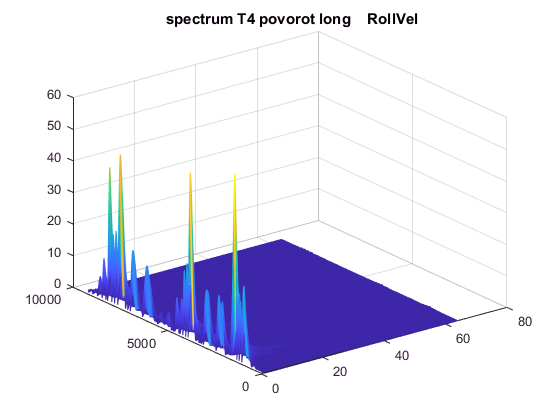

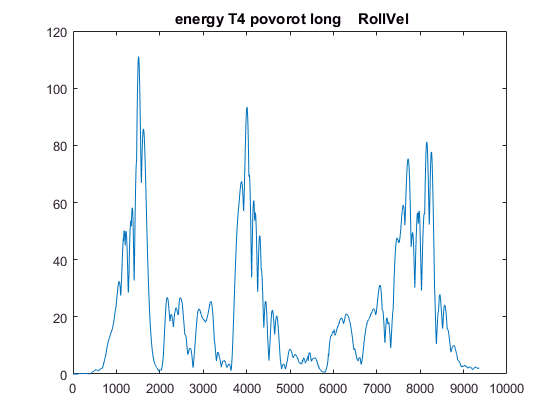

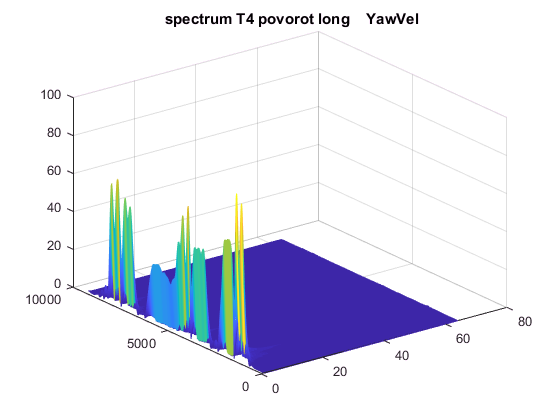

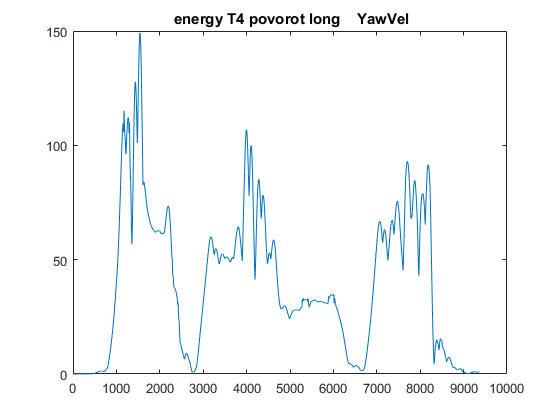

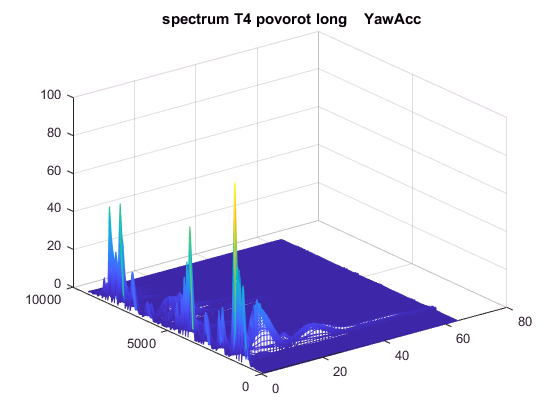

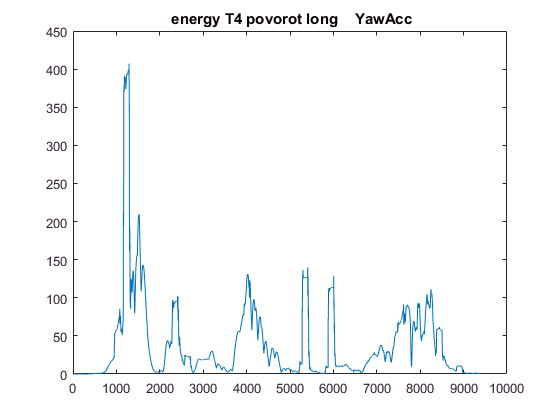

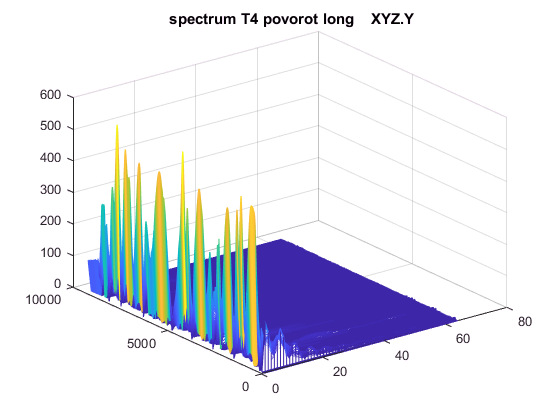

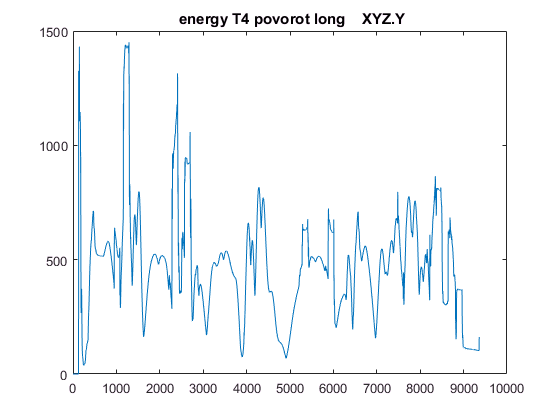

testDan1.Spectrum(["RollVel", "YawVel", "YawAcc", "XYZ.Y"], SetParamFFT);

XYZ.Y


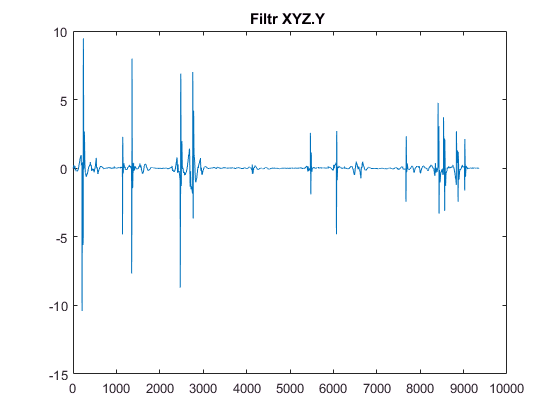

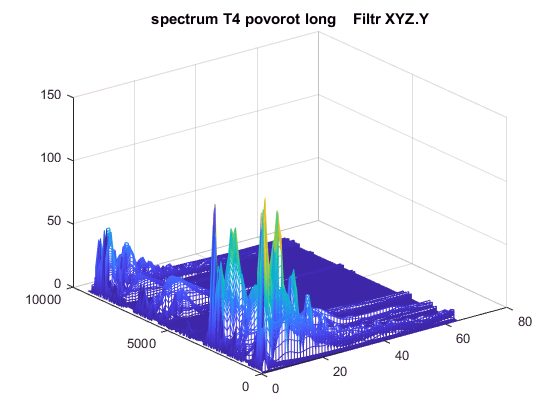

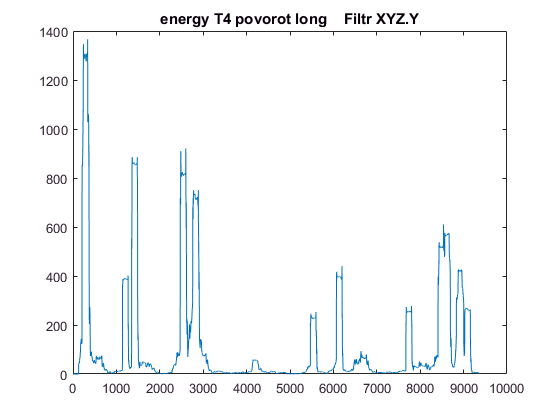

testDan1.FiltrSvchChebSpectrum("XYZ.Y", "Filtr XYZ.Y ");

%testDan1.PlotXnames(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
%zout=testDan1.Spectrum(["PitchVel", "RollVel", "YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);

%testDan1.PlotXYZg(["PitchVel", "RollVel", "YawVel", "YawAcc"])
%testDan.PlotXYZ()
% testDan1.vBelt();
% proskal = testDan1.Proskal();
%testDan1.PlotXnames(["PitchVel","YawVel", "YawAcc", "Engine.Trq", "Engine.Rotv", "XYZ.X", "XYZ.Y", "XYZ.Z"]);
% zout=testDan1.Spectrum(["YawVel", "YawAcc", "XYZ.X", "XYZ.Y", "XYZ.Z"], SetParamFFT);
% testDan1.PlotXnames(["Frc.X", "Frc.Z", "muRoad.R"]);
% testDan1.mU();                

vBelt.R


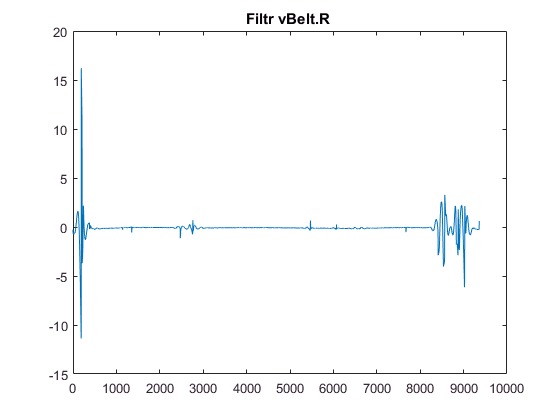

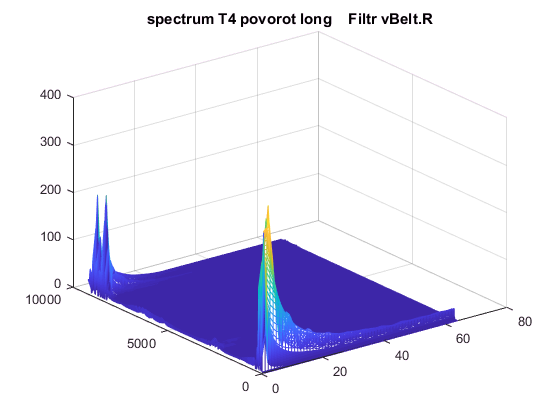

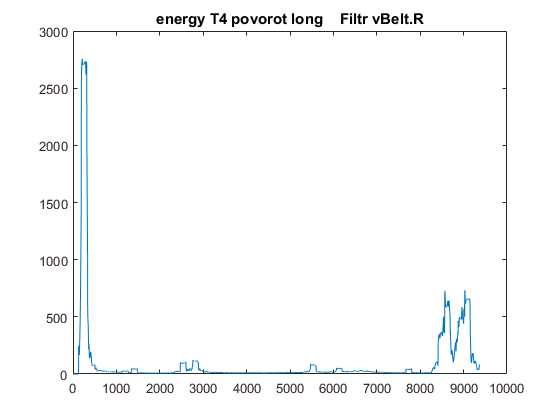

vBelt.R


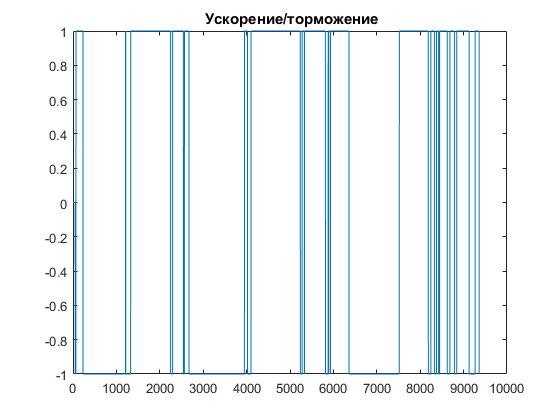

testDan1.FiltrSvchChebSpectrum("vBelt.R", "Filtr vBelt.R ");

Time
YawVel


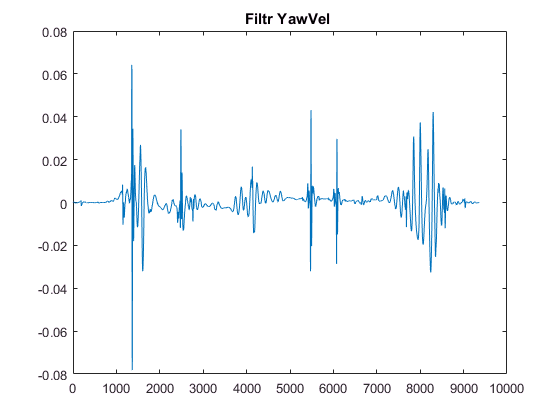

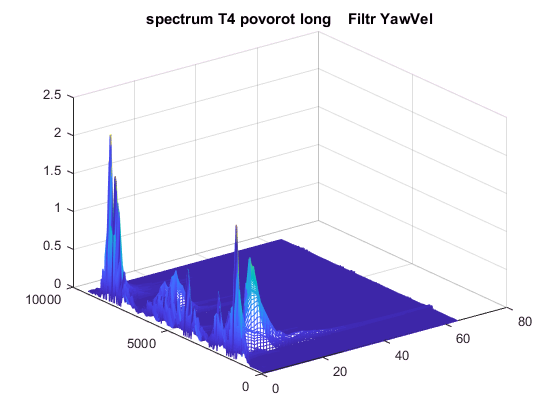

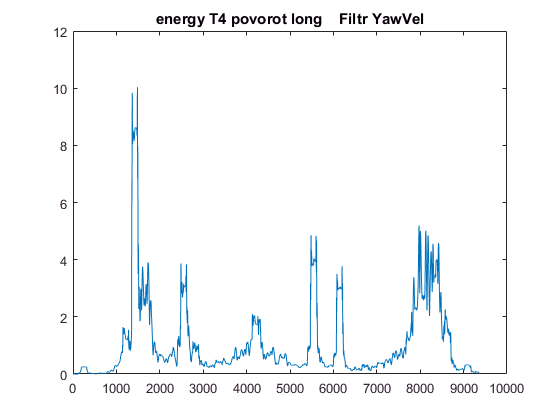

mfilter = MFilter();

%zzz = mfilter.FSVCH_Cheb(testDan1.Dan.Get("YawVel"));

testDan1.FiltrSpectrumBasa(testDan1.Dan.Get("Time"), mfilter.FSVCH_Cheb(testDan1.Dan.Get("YawVel")), "Filtr YawVel ")
